# 100:1 DC Motor Characterization

## 1. Create test data

maxPWM = 1.00;% maximum duty cycle
incrPWM = 0.05;% PWM increment
PWMcmdRaw = (-maxPWM:incrPWM:maxPWM)';  % column vector of duty cycles from -1 to 1

## 2. Create and initialize device objects

%% 2. Create and initialize device objects 

clear a dcm carrier enc              % Delete existing device objects

a = arduino('COM8','Nano33IoT',"Libraries",{"motorCarrier","rotaryEncoder"});

Updating server code on board Nano33IoT (COM8). This may take a few minutes.


carrier = motorCarrier(a);
dcm2 = dcmotor(carrier,'M2');         % Connect a DC motor at 'M2' port on the Arduino Nano Motor Carrier board
dcm1 = dcmotor(carrier,'M1');         % Connect a DC motor at 'M1' port on the Arduino Nano Motor Carrier board

enc2 = rotaryEncoder(carrier,2);      % Connect the encoder of 'M2' at the encoder port 2 on the Arduino Nano Motor Carrier board
enc1 = rotaryEncoder(carrier,1);      % Connect the encoder of 'M1' at the encoder port 1 on the Arduino Nano Motor Carrier board

## 3. Measure raw motor speed for each PWM command

speedRaw2 = zeros(size(PWMcmdRaw));              % Preallocate vector for speed measurements
speedRaw1 = zeros(size(PWMcmdRaw));              % Preallocate vector for speed measurements

dcm2.Speed = 0;
dcm1.Speed = 0;
gearRatio = 100;                                % As per the motor spec sheet, gear ratio equals 100:1

start(dcm2)                                      % Turn on motor
start(dcm1)                                      % Turn on motor

for ii = 1:length(PWMcmdRaw)

    dcm2.Speed = PWMcmdRaw(ii);
    dcm1.Speed = PWMcmdRaw(ii);
    pause(1)                                    % Wait for steady state

    speedRaw2(ii) = readSpeed(enc2)/gearRatio;    % read motor speed in rpm of the output shaft
    speedRaw1(ii) = readSpeed(enc1)/gearRatio;    % read motor speed in rpm of the output shaft

end

stop(dcm2)                                       % turn off motor
stop(dcm1)                                       % turn off motor
dcm2.Speed = 0;
dcm1.Speed = 0;

## 4. Post-process and save data

%% 4. Post-process and save data

idx = (diff(speedRaw2) > 0);             % find indices where vector is increasing
speedMonoL = speedRaw2(idx);              % Keep only increasing values of speed
PWMcmdMonoL = PWMcmdRaw(idx);            % Keep only corresponding PWM values
PWMcmdMonoL(speedMonoL == 0) = 0;         % enforce zero power for zero speed

idx = (diff(speedRaw1) > 0);             % find indices where vector is increasing
speedMonoR = speedRaw1(idx);              % Keep only increasing values of speed
PWMcmdMonoR = PWMcmdRaw(idx);            % Keep only corresponding PWM values
PWMcmdMonoR(speedMonoR == 0) = 0;         % enforce zero power for zero speed

save motorResponseL PWMcmdMonoL speedMonoL PWMcmdMonoR speedMonoR % save post-processed measurements

## 5. Graph raw and post-processed data

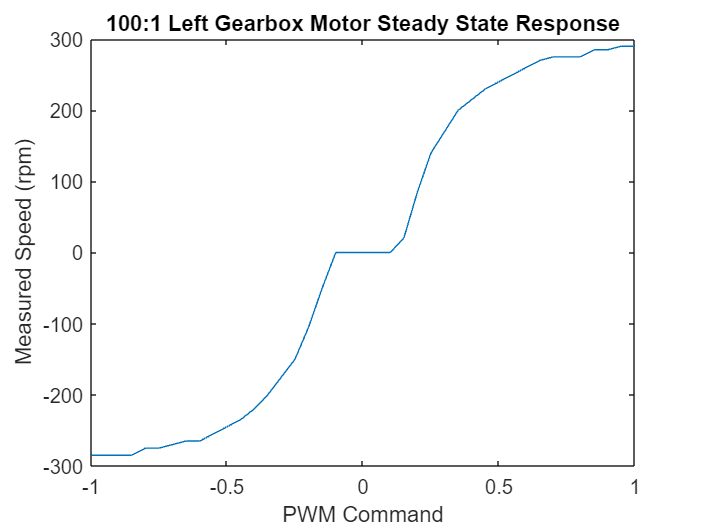

%% 4. Graph raw data

plot(PWMcmdRaw,speedRaw2)      % raw speed measurements
title('100:1 Left Gearbox Motor Steady State Response')
xlabel('PWM Command')
ylabel('Measured Speed (rpm)')

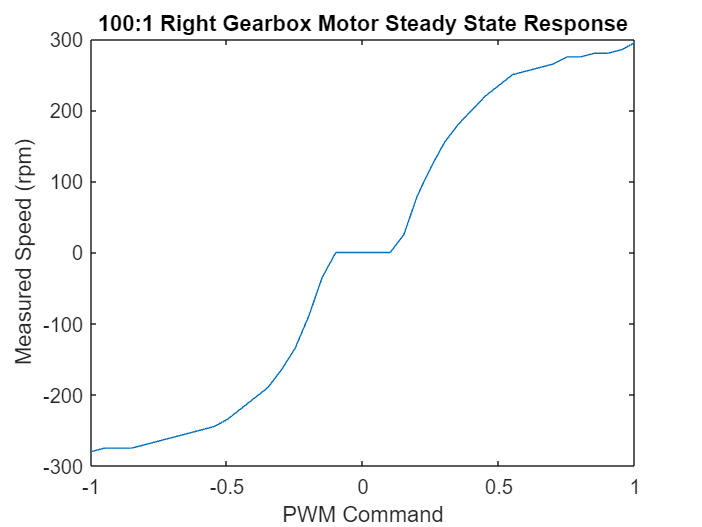


plot(PWMcmdRaw,speedRaw1)      % raw speed measurements
title('100:1 Right Gearbox Motor Steady State Response')
xlabel('PWM Command')
ylabel('Measured Speed (rpm)')

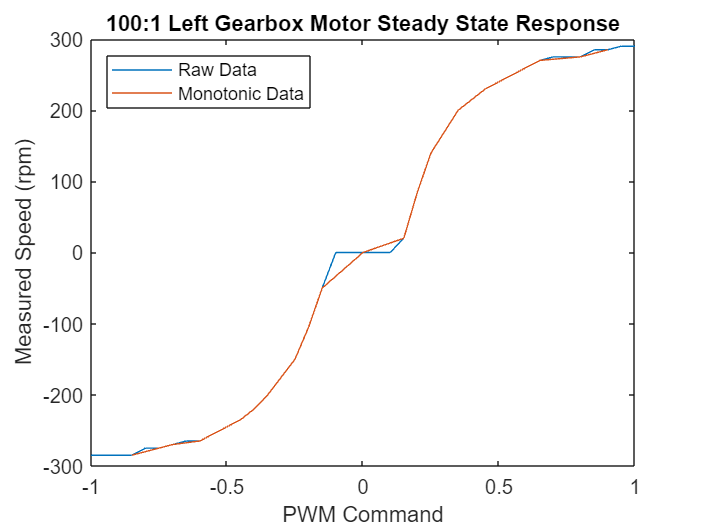


%% 5. Graph raw and post-processed data

plot(PWMcmdRaw,speedRaw2)                            % raw speed measurements
hold on
plot(PWMcmdMonoL,speedMonoL)                          % non-monotonic measurements filtered out
title('100:1 Left Gearbox Motor Steady State Response')
xlabel('PWM Command')
ylabel('Measured Speed (rpm)')
legend('Raw Data','Monotonic Data','Location','northwest')
hold off;

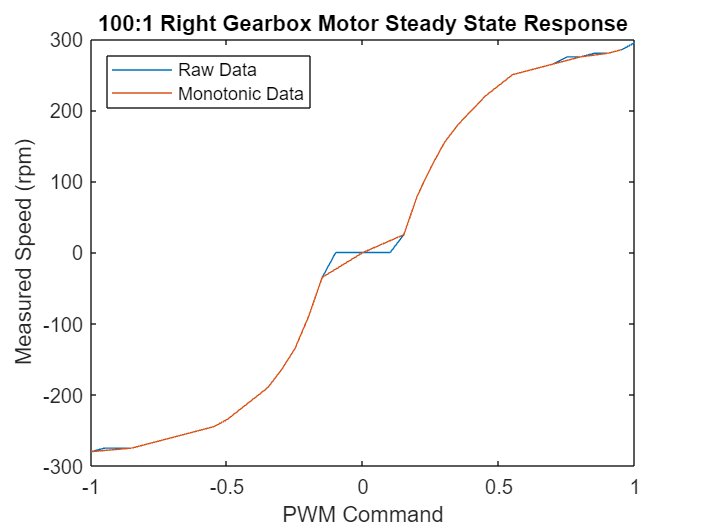


plot(PWMcmdRaw,speedRaw1)                            % raw speed measurements
hold on
plot(PWMcmdMonoR,speedMonoR)                          % non-monotonic measurements filtered out
title('100:1 Right Gearbox Motor Steady State Response')
xlabel('PWM Command')
ylabel('Measured Speed (rpm)')
legend('Raw Data','Monotonic Data','Location','northwest')
hold off;

## 6. Delete device objects

clear a dcm2 dcm1 carrier enc2 enc1

*Copyright 2018 The MathWorks, Inc.*